# Part 6: Correlations

[*Return to introduction*](matlab: edit S1_Introduction.mlx)

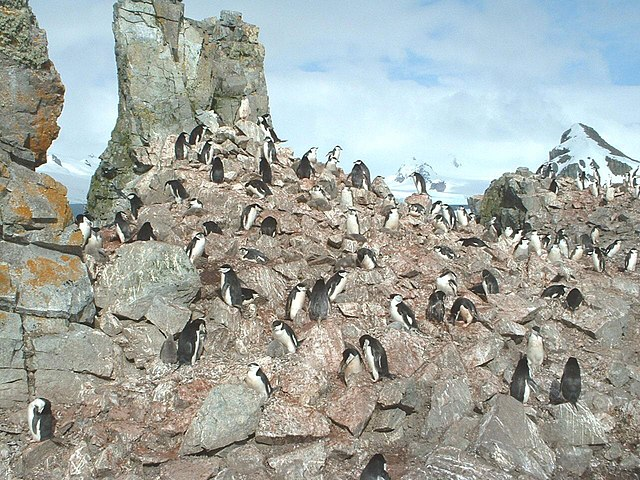

A chinstrap penguin breeding colony (also called a [rookery](https://commons.wikimedia.org/wiki/File:The_World_Factbook_-_Antarctica_-_Flickr_-_The_Central_Intelligence_Agency_(6).jpg)). 

You should complete the prior live scripts in this statistics curriculum module before starting this one. If you need to reload any variables, this block of code will add `penguins` to your workspace and clean it up: 

filename = "penguins.csv";
penguins = readtable(filename);
penguins.species = categorical(penguins.species);
penguins.island = categorical(penguins.island);
penguins.sex = categorical(penguins.sex);
penguins1 = rmmissing(penguins);
chinstrap = penguins1(penguins1.species == "Chinstrap",:);
gentoo = penguins1(penguins1.species == "Gentoo",:); 
adelie = penguins1(penguins1.species == "Adelie",:);

## Find the correlation between any two variables

Another way to look at the relationship between two variables is to look at the [correlation](https://en.wikipedia.org/wiki/Correlation) between them. The correlation between two variables is a measure of how linearly related the two variables are. The degree of correlation between two variables is expressed as a 'correlation coefficient'. This coefficient is often called R and is the precursor to [R-squared](matlab:open('./S5_Predictive_modeling.mlx')) (R-squared is quite literally the value of R, squared (R^2)). 

A type of correlation coefficient you'll see a lot is the[ *Pearson correlation coefficient*](https://en.wikipedia.org/wiki/Pearson_correlation_coefficient). It is calculated by determining how likely two variables are to vary together (if one goes up, does the other go up as well? Do the variables behave similarly?) and then dividing this covariance by the multiplication of both variables' standard deviation. 

As always, MATLAB® has a handy function for this so we can avoid going too deep into the math weeds here. [`corrcoef`](https://www.mathworks.com/help/matlab/ref/corrcoef.html)(x,y) gives the correlation coefficient between x and y. 

The output can be between -1 and 1, with 1 indicating a perfect positive correlation between x and y (both variables move in the same direction), and -1 would mean a perfect negative correlation (as one variable moves up, the other moves down, but they're still perfectly in sync, sometimes called anticorrelated). 

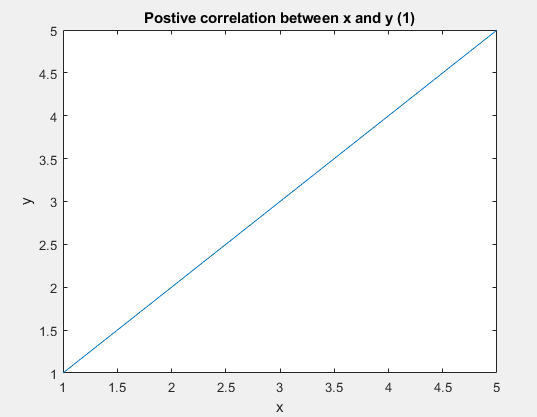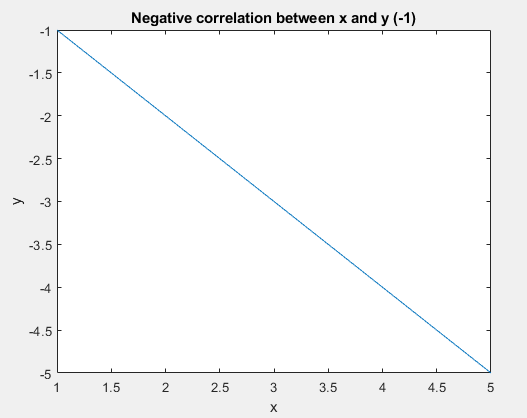

Let's try `corrcoef()`:

corrcoef(penguins1.body_mass_g, penguins1.flipper_length_mm)

The output prints as a matrix of the correlation coefficients between any two variables. 

Here's the output and a key to understanding what's shown: 

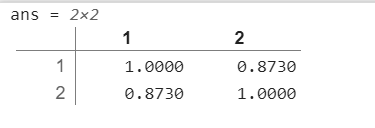

1, 1: [correlation of x with x-- this is 1! ]             1, 2:    [correlation of y with x ]

2, 1: [correlation of x with y]                               2, 2:    [correlation of y with y--- this is 1!]

The diagonal is a value of 1 because you are finding the correlation of a variable with itself which will always be perfectly correlated. 

It's helpful to be able to look at the correlation between several different variables at once to see what is predictive in your dataset. 

A tiny bit of housekeeping first: the correlation between words and a number doesn't make sense, so we need to remove the text columns of our table. 

Let's keep all the rows (all penguins) in our table, but index the columns such that any columns with text data types are removed:

penguins_numonly = penguins1(:,3:end-1); 

The `corrcoef()` function doesn't understand tables, so let's quickly [convert our table to an array](https://www.mathworks.com/help/matlab/ref/table2array.html#description) (using `table2array`): 

penguins_numonly = table2array(penguins_numonly)

Now we have 333 rows (number of penguins) and 4 columns (penguin feature variables). Let's find the correlation between all 4 of those variables. 

  Type the following code into the code block: 

We have a correlation matrix of the values of correlation between each variable and all the other variables. How can we visualize this? 

## Visualize correlations between variables 

A common way is to make a [**heatmap**](https://www.mathworks.com/help/matlab/ref/heatmap.html), which displays the data in a matrix form, where the color of  each block shows how strong the correlation between any 2 variables is. 

Run:

var_names = ["Bill Depth", "Bill Length", "Flipper Length", "Body Mass"];
heatmap(var_names, var_names, CorrMat)

 We can see that the darker the blue, the more positively correlated the two variables are. Which variables are the most positively correlated (close to 1) based on this map? Which are the most negatively correlated (close to -1)?

You can imagine how helpful a map like this would be in terms of determining which parts of your dataset might be the most interesting or predictive. 

This map is a bit monochromatic, making it a little harder to quickly see what the patterns in this data are. There are a few things you can adjust to make the heatmap a bit easier to read. 

Sometimes it can be really helpful to change the color a little bit so your map is more intuitive to read. 

This code removes the values of 1 from the diagonal of `CorrMat`, because they are meaningless. You don't need to fully understand this code, just know that you can make this adjustment if you'd like: 

CorrMat(eye(size(CorrMat)) == 1) = nan;

If you don't particularly care whether the correlation is positive or negative (we don't!) but just care about how large the dependence between the two variables is, you can take the absolute value of the correlation values. The function [`abs()`](https://www.mathworks.com/help/matlab/ref/abs.html) does this for us.  

heatmap(var_names, var_names, abs(CorrMat), "Colormap", parula)

  `heatmap()` has an option for adjusting the colormap. We've started with parula here. Change the value of [colormap](https://www.mathworks.com/help/matlab/ref/colormap.html) in the dropdown and see what makes the data stand out to you. 

Note that the flipper length is most highly correlated with body mass - this makes sense! As penguins get larger, they will need longer flippers to support their body weight while swimming.

## Compare correlations between species

In the field, you might want to compare different penguin species to each other. A high correlation between two species of penguins might suggest that they evolved very closely together and only recently split into distinct species, for example.

We can make one large array of all our penguin data broken up by species and make a heat map in the same way we just did.

As we did with the overall penguins table, for each species we can remove the columns with strings. In terms of rows, we can only consider 68 penguins per species. This is because there are only 68 chinstrap penguins so that number limits the comparisons we can make. The first thing we will do is randomly select 68 rows from `gentoo` and 68 rows from `adelie`.

rows_gent = datasample([1:height(gentoo)], 68, "Replace", false);
rows_ad = datasample([1:height(adelie)],68, "Replace", false);

`datasample(data, n) `randomly samples `n` values (in this case, 68) from the `data` (in this case, the rows in each table)`.` Setting the "Replace" option to false means that each row can only be selected once, so all 68 penguin rows selected will be unique.

As before, we are also converting each table to an array. Finally, we can concatenate our arrays of each species into one big matrix that allows us to find the correlation between each variable for each species. This just means adding the rows of the 2nd and 3rd arrays to the first so that we have a variable called concat that has 68 rows and 12 columns. 

concat = [table2array(gentoo(rows_gent, 3:end-1)), table2array(adelie(rows_ad, 3:end-1)), table2array(chinstrap(:, 3:end-1))];

Let's find the correlations between variables and then plot them, as before: 

corr_allspecies = corrcoef(concat);
var_names = ["gent Bill Depth", "gent Bill Length", "gent Flipper Length", "gent Body Mass", "ad Bill Depth", "ad Bill Length", "ad Flipper Length", "ad Body Mass", "chin Bill Depth", "chin Bill Length", "chin Flipper Length", "chin Body Mass"];
corr_allspecies(eye(size(corr_allspecies)) == 1) = nan; % as before, you can remove the ones along the diagonal if you wish

heatmap(var_names, var_names, abs(corr_allspecies), "Colormap",parula) 

From this map, it is very clear which variables are the most highly correlated with one another. You can see that within each species, there are relatively high correlations between variables, but correlations between species are low. For example, Adelie depth is not highly correlated with Gentoo bill depth, and so on. This tells us that all three of these species have evolved pretty differently, at least along the dimensions that are measured here! You can imagine how this would be useful to a scientist in the field trying to work out an organism's evolutionary tree. 

[*Continue to next section (Hypothesis Testing)*](matlab: edit S7_Hypothesis_testing.mlx)

[*Return to introduction*](matlab: edit S1_Introduction.mlx)